% === Ruta de carpeta con modelos ThermoKernel ===
folderThermo = '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/GEMs cancer/Models/';
filesTK = dir(fullfile(folderThermo, '*.mat'));

% Filtrar solo archivos que parecen modelos válidos (opcional)
filesTK = filesTK(~[filesTK.isdir]); % evita carpetas

numFiles = length(filesTK);
modelsThermo = cell(numFiles,1);
rxnsThermo = cell(numFiles,1);
modelNames = cell(numFiles,1);

% Cargar modelos ThermoKernel con manejo de errores
fprintf('Cargando %d modelos...\n', numFiles);

Cargando 1226 modelos...


for i = 1:numFiles
    try
        modelTK = readCbModel(fullfile(folderThermo, filesTK(i).name));
        modelsThermo{i} = modelTK;
        rxnsThermo{i} = modelTK.rxns;
        modelNames{i} = erase(filesTK(i).name, '.mat');
    catch ME
        warning('Error al cargar modelo %s: %s', filesTK(i).name, ME.message);
        modelsThermo{i} = [];
        rxnsThermo{i} = {};
        modelNames{i} = erase(filesTK(i).name, '.mat');
    end
end

Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.subSystems{x} is a character array, and this format is retained.
Each model.s


% Inicializar matriz de intersecciones
interMatrix = zeros(numFiles);

fprintf('Calculando matriz de intersecciones...\n');

Calculando matriz de intersecciones...


% Usar parfor para acelerar (requiere Parallel Toolbox)
parfor i = 1:numFiles
    tempRow = zeros(1,numFiles);
    for j = i:numFiles % solo mitad superior (matriz simétrica)
        if isempty(rxnsThermo{i}) || isempty(rxnsThermo{j})
            tempRow(j) = 0;
        else
            common = intersect(rxnsThermo{i}, rxnsThermo{j});
            denom = mean([length(rxnsThermo{i}), length(rxnsThermo{j})]);
            if denom > 0
                tempRow(j) = length(common) / denom;
            else
                tempRow(j) = 0;
            end
        end
    end
    interMatrix(i,:) = tempRow;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 11 workers.
Parallel pool using the 'Processes' profile is shutting down.


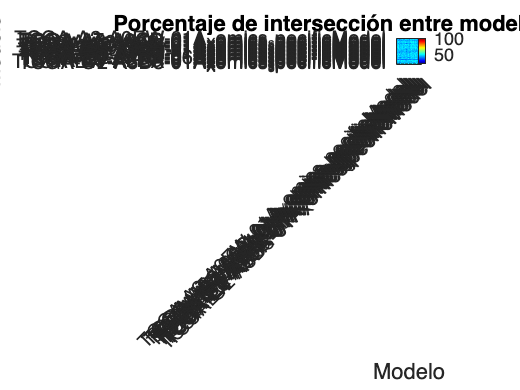


% Completar la parte inferior de la matriz (simétrica)
for i = 2:numFiles
    for j = 1:i-1
        interMatrix(i,j) = interMatrix(j,i);
    end
end

% Mostrar como heatmap (con cuidado si son muchos modelos)
figure;
imagesc(interMatrix * 100);
colormap(jet);
colorbar;
title('Porcentaje de intersección entre modelos ThermoKernel');
xlabel('Modelo');
ylabel('Modelo');
axis square;

% Mejor manejo de ticks si hay muchos modelos
if numFiles <= 50
    xticks(1:numFiles);
    yticks(1:numFiles);
    xticklabels(modelNames);
    yticklabels(modelNames);
    xtickangle(45);
else
    % Muestra solo algunos ticks para no saturar
    stepTick = ceil(numFiles/20);
    ticks = 1:stepTick:numFiles;
    xticks(ticks);
    yticks(ticks);
    xticklabels(modelNames(ticks));
    yticklabels(modelNames(ticks));
    xtickangle(45);
end

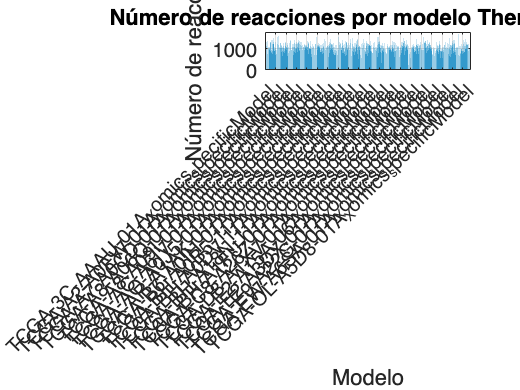


% === Número de reacciones por modelo ===
numRxnsTK = cellfun(@length, rxnsThermo);

% === Gráfico de barras ===
figure;
bar(numRxnsTK, 'FaceColor', [0.2 0.6 0.8]);
title('Número de reacciones por modelo ThermoKernel');
xlabel('Modelo');
ylabel('Número de reacciones');
if numFiles <= 50
    xticks(1:numFiles);
    xticklabels(modelNames);
else
    stepTick = ceil(numFiles/20);
    ticks = 1:stepTick:numFiles;
    xticks(ticks);
    xticklabels(modelNames(ticks));
end
xtickangle(45);
grid on;

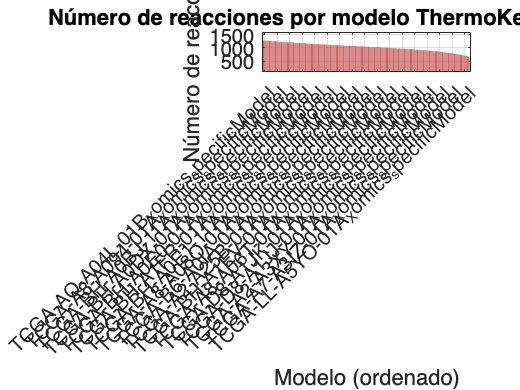

% === Ordenar modelos por número de reacciones ===
[~, sortIdx] = sort(numRxnsTK, 'descend');
sortedNames = modelNames(sortIdx);
sortedNumRxns = numRxnsTK(sortIdx);

figure;
bar(sortedNumRxns, 'FaceColor', [0.8 0.4 0.4]);
title('Número de reacciones por modelo ThermoKernel (ordenado)');
xlabel('Modelo (ordenado)');
ylabel('Número de reacciones');
if numFiles <= 50
    xticks(1:numFiles);
    xticklabels(sortedNames);
else
    stepTick = ceil(numFiles/20);
    ticks = 1:stepTick:numFiles;
    xticks(ticks);
    xticklabels(sortedNames(ticks));
end
xtickangle(45);
grid on;

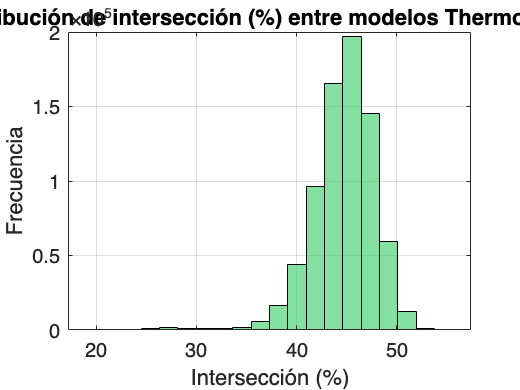


% === Histograma de intersecciones ===
upperTri = triu(interMatrix, 1); % solo parte superior sin diagonal
vals = upperTri(upperTri > 0); % evitar ceros de la parte no calculada

figure;
histogram(vals * 100, 20, 'FaceColor', [0.2 0.8 0.4], 'EdgeColor', 'k');
title('Distribución de intersección (%) entre modelos ThermoKernel');
xlabel('Intersección (%)');
ylabel('Frecuencia');
grid on;

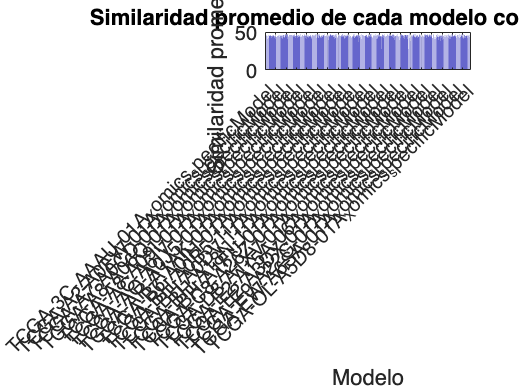


% === Similaridad promedio por modelo ===
avgSimilarity = mean(interMatrix, 2, 'omitnan');

figure;
bar(avgSimilarity * 100, 'FaceColor', [0.4 0.4 0.8]);
title('Similaridad promedio de cada modelo con los demás');
xlabel('Modelo');
ylabel('Similaridad promedio (%)');
if numFiles <= 50
    xticks(1:numFiles);
    xticklabels(modelNames);
else
    stepTick = ceil(numFiles/20);
    ticks = 1:stepTick:numFiles;
    xticks(ticks);
    xticklabels(modelNames(ticks));
end
xtickangle(45);
grid on;


% === Guardar resultados en tabla ===
T = table(modelNames(:), numRxnsTK(:), avgSimilarity(:), ...
    'VariableNames', {'Modelo', 'NumReacciones', 'SimilaridadPromedio'});
writetable(T, fullfile(folderThermo, 'Resumen_Modelos_ThermoKernel.csv'));

fprintf('Análisis completado. Resultados guardados en Resumen_Modelos_ThermoKernel.csv\n');

Análisis completado. Resultados guardados en Resumen_Modelos_ThermoKernel.csv


% === Exportar matriz de intersección ===
matrizTable = array2table(interMatrix * 100, ...  % en porcentaje
    'VariableNames', modelNames, ...
    'RowNames', modelNames);

writetable(matrizTable, ...
    fullfile(folderThermo, 'Matriz_Interseccion_ThermoKernel.csv'), ...
    'WriteRowNames', true);

fprintf('Matriz de intersección exportada a Matriz_Interseccion_ThermoKernel.csv\n');

Matriz de intersección exportada a Matriz_Interseccion_ThermoKernel.csv
